# Exercise 3

## Summing Potentials for Robot Control

### About This Exercise

You've created the two basic potential functions needed to drive the robot: the 'bowl' potential with the minimum at the goal, and the 'obstacle' potential with steep barriers for avoiding obstacles. In general, you'll just have one goal at any given time and any number of obstacles. Thus, we should create function that takes in a goal and any number of obstacles (as polygons) and returns the gradient of the potential function, which will determine the control, otherise known as the Potential Planner. 

The Potential Planner works by driving the robot down the steepest gradient towards the global minimum located at the goal. However, when adding multiple obstacles together, the result may contain local minimum where the robot will get stuck. In this exercise, we'll explore when local minima can occur.

 **By the end of this exercise, you'll be able to: **

- **Combine obstacle and goal potentials into a potential function with gradients.**

### calculatePotential

First you'll write a function that uses the functions from the previous two lessons to calculate the potential and the gradient given a goal and any number of obstacles.

[► Write the calculatePotential function](matlab:open('./calculatePotential.mlx'))

Once complete, follow the steps below to explore what happens when we have multiple obstacles in close proximity.

#### Calculate and Visualize

- Set the goal and parameters C and Q.

goal_x = -2;
goal_y = -2;
C = 0.5; %Change value here [0,1]

- Here we'll create two circular obstacles close to each other. We will store them in a struct called obstacles with the fields poly, C, and Q for use in our new calculatePotential function.

center = [1,-1; -1 1]

center =      1    -1
    -1     1


radius = 1.1;
th = linspace(0,2*pi,21)

th =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832


C_obs = 1;
Q_obs = 1.5;
for i = 1:size(center,1)
    obstacles(i).poly = [center(i,1)+radius*cos(th(1:end-1)'), ...
                         center(i,2)+radius*sin(th(1:end-1)')];
    obstacles(i).C = C_obs;
    obstacles(i).Q = Q_obs;
end

- Now we will use the calculatePotential function

dx = 0.1;
x = -4:dx:4;
y = x;
[X,Y] = meshgrid(x,y);
[U, dUdx, dUdy] = calculatePotential(X,Y,[goal_x, goal_y],obstacles,C);

- Plot potentials. This time we plot both the 3D surface plot as well as a 2D contour plot where you can more clearly see the local minimu that occurs.

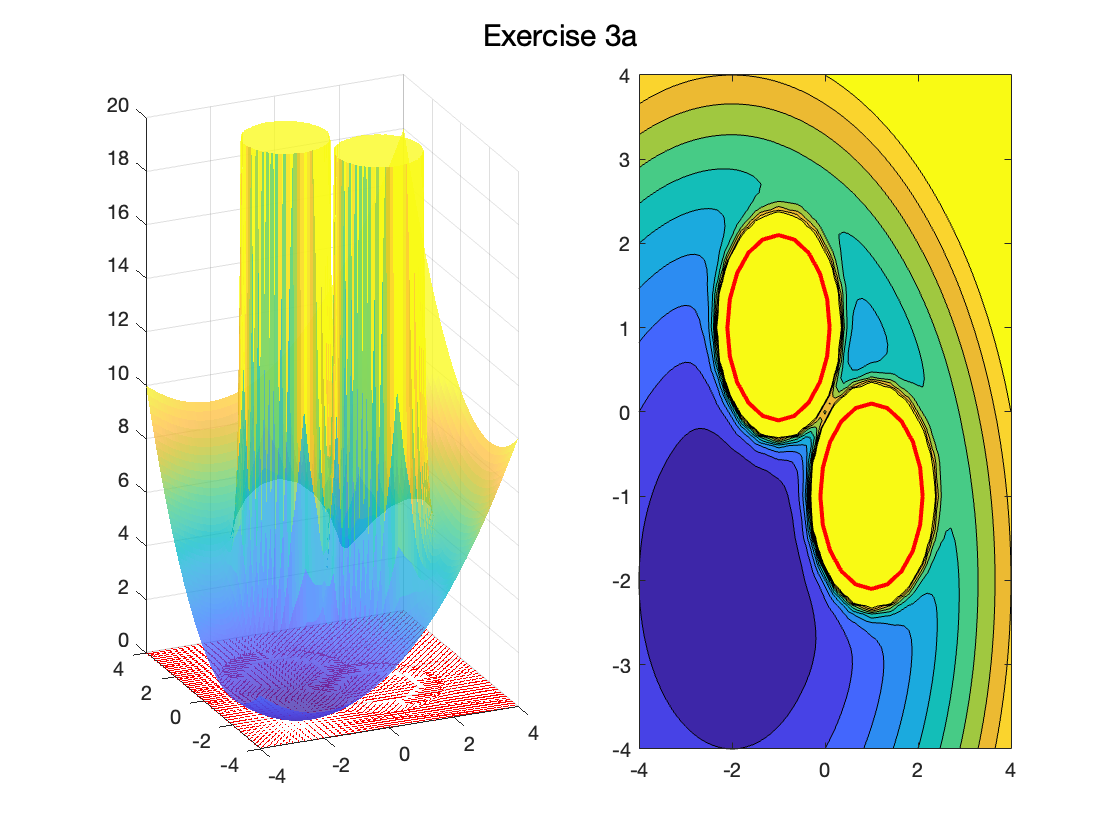

plot_title = "Exercise 3a"; 
[indx, indy] = plotTotalPotential(dUdx, dUdy, X, Y, U, obstacles, plot_title);

This function will animate the robot using the control derived from the potential function trying to navigate to the goal (denoted by the cyan asterisk). 

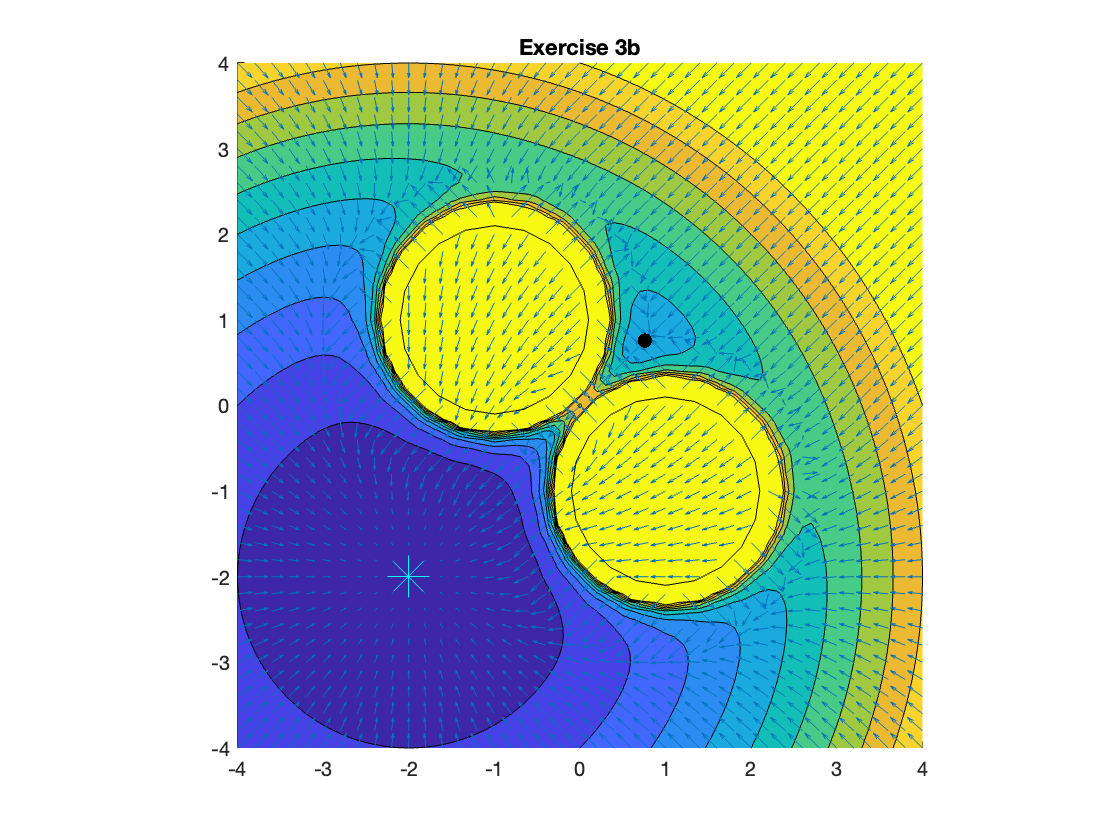

start_x = 2.5;
start_y = 3.5;
plot_title = "Exercise 3b"; 
animate_robot3(X, indx, indy, Y, dUdx, dUdy, start_x, start_y, goal_x, goal_y, C,obstacles,U, plot_title);

 Is your robot able to get to the goal? Does it get stuck in a local minimum?How might you get out of this local minimum? Alter the potential function to try to avoid getting stuck in the local minima. 

### Finished!

Now that you've created a generalized function that converts a goal point and any number of obstacles into a potential function with its gradients, feel free to try to populate the landscape with a variety of obstacles to see how the robot moves. In the next exercise, you will use feedback linearization to see how this method would work for a differential drive robot.